# Preprocess taxi dataset

`taxiTable = basicPreprocessing(taxiTable)` removes trips containing incorrect, missing, or extreme values from `taxiTable`. In addition, new features for trip duration and average speed are added to `taxiTable` as variables `Duration` and `AveSpeed`. 

Charges and trip information that are negative, as well as charges inconsistent with expected values are considered incorrect. In addition, trips with pickup or drop off locations outside a geographic region of interest are removed.

function taxiTable = basicPreprocessingModified(taxiTable)

#### Remove invalid charges

Only keep trips (rows) containing valid charges.

% The following code was captured using Live Editor tools
taxiTable = taxiTable(taxiTable.RateCode ~= "99", :);   % Valid rate code
taxiTable = taxiTable(taxiTable.Fare > 0, :);           % Valid fare
taxiTable = taxiTable(taxiTable.ExtraCharge >= 0, :);   % Positive charge
taxiTable = taxiTable(taxiTable.Tax > 0, :);            % Valid tax
taxiTable = taxiTable(taxiTable.Tip >= 0, :);           % Positive tip
taxiTable = taxiTable(taxiTable.Tolls >= 0, :);         % Positive toll
taxiTable = taxiTable(taxiTable.ImpSurcharge >= 0, :);  % Positive charge
taxiTable = taxiTable(taxiTable.TotalCharge > 0, :);    % Valid total

Only keep trips where charges match the expected values. 

- ImpSurcharge is $0.30

- Tax is $0.50

- Total is the sum of all charges

taxiTable = taxiTable(abs(taxiTable.ImpSurcharge-0.3) < 0.01, :); 
taxiTable = taxiTable(abs(taxiTable.Tax-0.5) < 0.01, :); 
taxiTable = taxiTable(abs(taxiTable.Fare + taxiTable.ExtraCharge + taxiTable.Tax + taxiTable.Tip + taxiTable.Tolls + taxiTable.ImpSurcharge - taxiTable.TotalCharge) < 0.01, :);

#### Remove invalid trip information

Only keep trips with valid passenger and distance information.

% The following code was captured using Live Editor tools
taxiTable = taxiTable(taxiTable.Passengers > 0, :);     % At least 1 passenger
taxiTable = taxiTable(taxiTable.Distance > 0, :);       % Valid trip distance

Remove trips missing valid pickup or drop off locations.

taxiTable = standardizeMissing(taxiTable, 0, "DataVariables", ["PickupLat","PickupLon","DropoffLat","DropoffLon"]);
taxiTable = rmmissing(taxiTable, "DataVariables", ["PickupLat","PickupLon","DropoffLat","DropoffLon"]);

#### Add trip features

Add two new variables to the table

- `Duration` - Length of the trip, in minutes, calculated from the pickup and drop off times.

- `AveSpeed` - Average speed, in mph, calculated from the distance and duration values.

taxiTable = addDuration(taxiTable); % minutes
taxiTable = addAveSpeed(taxiTable); % mph

#### Remove outliers

Only keep trips with pickup and drop off locations inside the region of interest. The [`inpolygon`](https://www.mathworks.com/help/matlab/ref/inpolygon.html) function is used to find locations inside the box formed by the coordinates below.

% Bounding latitude/longitude
lat = [40.5612 40.9637]; 
lon = [-74.1923 -73.5982]; 

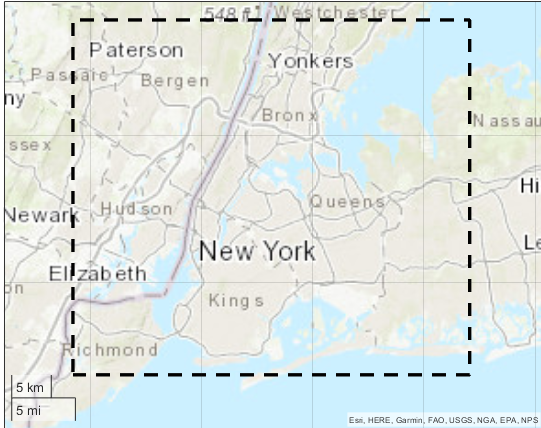

% Identify pickup and drop off locations inside the region of interest
inROI = inpolygon(taxiTable.PickupLat,taxiTable.PickupLon, lat([1 2 2 1]),lon([1 1 2 2])) ...
    & inpolygon(taxiTable.DropoffLat,taxiTable.DropoffLon, lat([1 2 2 1]),lon([1 1 2 2]));

% Only keep trips that begin and end inside the region of interest.
taxiTable = taxiTable(inROI,:);

Only keep trips with typical values

% % Typical trip
% taxiTable = taxiTable(taxiTable.Duration >= 1 & taxiTable.Duration <= 120, :);      % minutes
% taxiTable = taxiTable(taxiTable.AveSpeed >= 0.1 & taxiTable.AveSpeed <= 100, :);    % mph
% taxiTable = taxiTable(taxiTable.Distance >= 0.01 & taxiTable.Distance <= 50, :);    % miles
% 
% % Typical charges
% taxiTable = taxiTable(taxiTable.Fare >= 0.01 & taxiTable.Fare <= 100, :);
% taxiTable = taxiTable(taxiTable.Tolls <= 20, :);
% taxiTable = taxiTable(taxiTable.TotalCharge >= 0.5 & taxiTable.TotalCharge <= 120, :);

end